# **Laura Calzoni 0001058438 ** -  **LEDS Exam: July 26, 2022**

clear all
close all
addpath ./Functions;

# Exercise 1: Estimation

N=5000;             % Number of samples
Student = 'Laura Calzoni';
Matriculation = '0001058438';
[Measurements] = IdentifyThis(N,Student,Matriculation);

% Collection of the samples
u=Measurements.u;   
y=Measurements.y;

time = [0:1:N-1]';

### **1.1 Model structure**

% Input
figure(1);
plot(time(1:N/10),u(1:N/10));

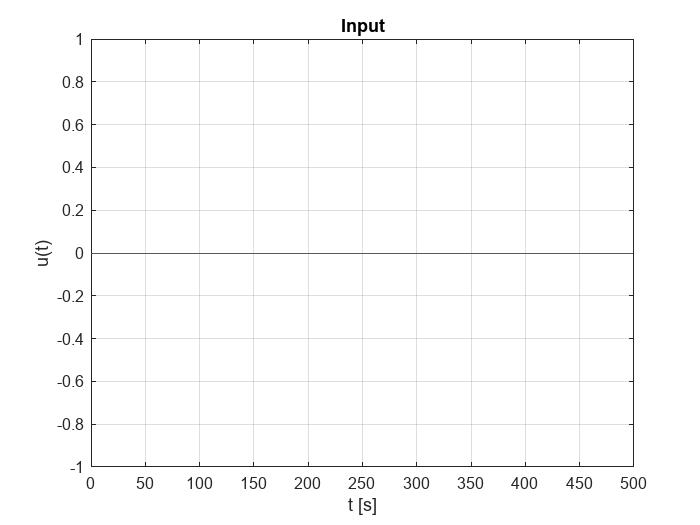

grid on;
ylabel('u(t)');
xlabel('t [s]');
title('Input');

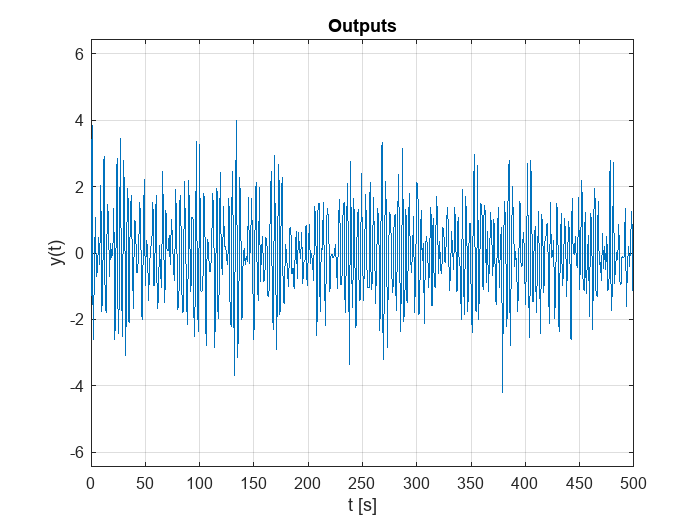

% Output
figure(2);
plot(time(1:N/10),y(1:N/10));
grid on;
ylabel('y(t)');
ylim([-max(y)*1.3 max(y)*1.3]);
xlabel('t [s]');
title('Outputs');

As the input is not present, we can conclude that we have an AR model, since the exogenous part is missing. Equation error models withouth input are called Time Series. In particular, Autoregressive Time Series are obtained when the equation error is modelled as a zero mean white process:

#### 
$$y(t) + a_1 y(t-1) + \dots + a_ny(t-n)  = e(t)$$

$$\;\to \;$$
 
$$y(t) =- a_1 y(t-1) - \dots -a_ny(t-n)  + w(t)$$


In these models, the error becomes a virtual input and so it's also called driving noise process:

%error as driving process
sigma_e=0.001;
e=randn(N,1);
e=e/std(e)*sqrt(sigma_e);     % White noise

The first request is to calculate and plot the output correlations up to delay 10. 

Autocorrelation is a way to express the similarity between the elements of a given series and a lagged verison of itself. It is a time domain measure of the stochastic process' memory. As a consequence, signals that have an high autocorrelation remain almost constant over time. 

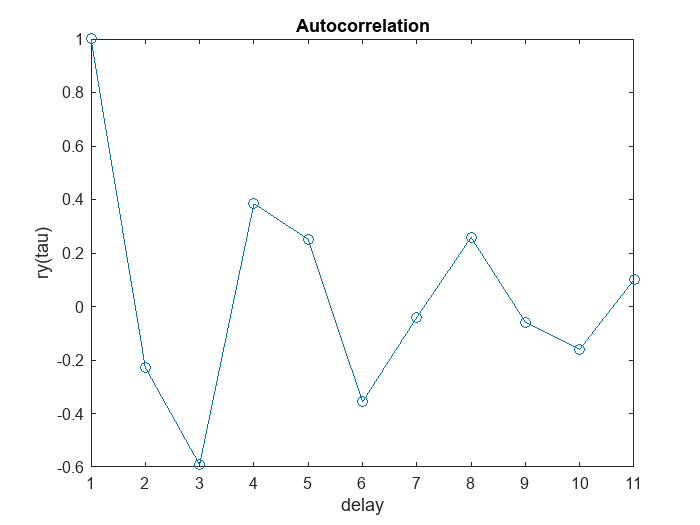

figure()
tau=10;         % Maximum delay to consider
ry = autocorr(y, tau);
grid on
plot (ry, '-o')
ylabel('ry(tau)');
xlabel('delay');
title('Autocorrelation');

As expected, we can notice from the plot that the autocorrelation tends to decrease. For an AR model:


$$r_{\varphi w} =E\left\lbrack \begin{array}{c}
-y\left(t-1\right)\\
-y\left(t-2\right)\\
\vdots \\
-y\left(t-n\right)
\end{array}\right\rbrack *w\left(t\right)=\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
0
\end{array}\right\rbrack$$


In fact, the previous output samples depend on the previous samples of $w\left(t\right)$*, *but since it's white it is completely uncorrelated with itself. As a consequence, also $y\left(t-\tau \right)$ results to be uncorrelated with $w\left(t\right)$.

### **1.2 Definition of the required estimation algorithm**

The system can be easily rewritten in Linear Regression form, which allows us to use the **Least Square (LS) method** to get a consistent estimate of the model's parameters $\hat{\theta} \left(t\right)$. As data are collected in real-time, instead of recomputing the entire estimate from the beginning everytime a new sample is avaible, recursive versions of the LS method are adopted. This allows to speed up the process, use less memory and reduce the computational effort required. Recursive identification algorithms, indeed, directly update the prevoius estimate of the parameter vector.

In particular, I have implemented both (the weigthed versions of) RLS III and RLS IV. Anyway, I'am going to expound only the latter, since it's the most commonly used. (To select the desired algorithm, just comment out the other one in the code).

The **RLS IV **directly updated the matrix $R^{-1} \left(t\right)$, defined as:

#### 
$$R\left(t\right)=\frac{1}{t}\sum_{k=1}^t \varphi \left(k\right)\varphi^T \left(k\right)$$


which converges to a sample covariance matrix. 

$R\left(t\right)$ can be updated as:

#### 
$$R\left(t\right)=\frac{t-1}{t}R\left(t-1\right)+\frac{\varphi \left(t\right)\varphi^T \left(t\right)}{t}$$


and every time a new data is available, I can compute my estimate as::

#### 
$$\hat{\theta} \left(t\right)={\left(\frac{1}{t}\sum_{k=1}^t \varphi \left(k\right)\varphi^T \left(k\right)\right)}^{-1} \frac{1}{t}\sum_{k=1}^t \varphi \left(k\right)y\left(k\right)$$


So, recursively, I can update my old paramether vector as:

#### 
$$\hat{\theta} \left(t\right)=\hat{\theta} \left(t-1\right)+\frac{{R\left(t\right)}^{-1} \varphi \left(t\right)}{t}\left(y\left(t\right)-\varphi^T \left(t\right)\hat{\theta} \left(t-1\right)\right)=\hat{\theta} \left(t-1\right)+K\left(t\right)\varepsilon \left(t\right)$$


To avoid to recompute the inverse of $R\left(t\right)$ at each iteration, the **Matrix Inversion Lemma** can be exploited:

#### 
$${\left(A+\textrm{BCD}\right)}^{-1} =A^{-1} -A^{-1} B{\left(C^{-1} +DA^{-1} B\right)}^{-1} DA^{-1}$$


Defining


$$\begin{array}{l}
A\;\to \;\frac{t-1}{t}R\left(t-1\right)\\
B\;\to \;\varphi \left(t\right)\\
C\;\to \frac{1}{t}\\
D\to \varphi^T \left(t\right)
\end{array}$$


I get the expression of the RLS IV with:

#### 
$${R\left(t\right)}^{-1} =\frac{t}{t-1}{R\left(t-1\right)}^{-1} -\frac{t}{t-1}\frac{{R\left(t-1\right)}^{-1} \varphi \left(t\right)\varphi^T \left(t\right){R\left(t-1\right)}^{-1} }{t-1+\varphi^T \left(t\right){R\left(t-1\right)}^{-1} \varphi \left(t\right)}$$


As recursive identification methods can be easily modified into real-time algorithms, they could be exploited also to track parameter's variations. However, as the estimate depends on all the previous samples, slow changes in the system cannot be easily and fastly detected. To overcome this problem, a forgetting factor $0<\lambda <1$ must be introduced in order to give more importance to recent data. 

The weighted version of the RLS IV, the **RWLS IV**, is obtained by setting $A\;\to \lambda *R\left(t-1\right)$, that leds to:

#### 
$${R\left(t\right)}^{-1} =\frac{1}{\lambda }\left({R\left(t-1\right)}^{-1} -\frac{{R\left(t-1\right)}^{-1} \varphi \left(t\right)\varphi^T \left(t\right){R\left(t-1\right)}^{-1} }{\lambda +\varphi^T \left(t\right){R\left(t-1\right)}^{-1} \varphi \left(t\right)}\right)$$


While the loss function to minimize to obtain the LS estimate becomes:

#### 
$$J\left(\theta \right)=\sum_{t=1}^N \lambda^{N-t} \varepsilon^2 \left(t\right)=\varepsilon^T W\varepsilon$$


with 


$$W=\left\lbrack \begin{array}{cccc}
\lambda^{N-1}  & 0 & \cdots  & 0\\
0 & \ddots  &  & \vdots \\
\vdots  &  & \lambda  & 0\\
0 & \cdots  & 0 & 1
\end{array}\right\rbrack$$
 

A crucial issue is the choice of $\lambda$, as it selects the memory of the algorithm: a small value of $\lambda$ assigns a greater importance to the most recent samples, as the other terms decrease faster, but also reduces a lot the accuracy of the estimation, as it is performed considering an insufficient number of data (trade-off). In general, $\left.\lambda \in \lbrack 0\ldotp 95\;,1\right\rbrack$. 

The RWLS IV algorithm is implemented in the function  [[theta] = myRWLSIV(y,n,alpha,lambda,theta_0,initial_point)](matlab:open('./Functions\myRWLSIV.m'))

The inputs of the function are: 

- the outpuy sequence *y*,

- the complexity of the system *n* (equal to the model order for AR system)

- a parameter *alpha *used to set the level of confidence we have in our initial estimate (high for low confidence)

- the forgetting factor *lambda*

- the initial estimate *theta_0*

- a parameter called *initial_point*, used to indicate the starting point of the recursive algorithm

As initial estimate, basically there could be two options:

- it's possible to start with an initial guess that should be a zero vector, as no information are provided. In this case, the iterations can start immediately ($\textrm{initial}\_\textrm{point}=0$) and $\textrm{alpha}$ should be selected large, as an hign correction is needed (the algorithm jumps quickly away from the initial state);

- after having collected a suitable number of data (at least equal to the number of parameter we have to identify), an **initial offline Batch estimate** can be computed. I decide to compute the LS batch on the first $10\cdot n$ samples, so, as a consequence, $initial\_point=10\cdot n\;$has to be set in this case. This choice leads to a more accurate estimation of the model's parameters, so I settle to go for this second option. Since in this way the initial estimate is obviously better, the parameter *alpha *can be selected small. The offline LS algorithm is implemented in the function  [[theta]=myLSbatch(y,n,N)](matlab:open('./Functions\myLSbatch.m')).

The functions will be evaluated inside the function used to estimate of the model order.

### **1.3 Estimation of the model order**

In order to estimate the model order $n$ I choose to use the **Minimum Description Length (MDL)** algorithm, because it provides consistency, it leads to lower complexity estimation with real data (parsimony) and it results in correct model order estimation when a true model exists. It belongs to the family of the so called Criteria with complexity terms.

#### 
$$\textrm{MDL}=N\;\log \left(J\left(\vartheta \right)\right)+2p\;\log \left(N\right)$$


The corresponding function [[mdl,minmdl,p] = myMDL(nmax,y)](matlab:open('./Functions\myMDL.m')) implements a for-loop where, at each iteration (i.e. for increasing value of the complexity *p*), I calculate the parameter vector (by means the RWLS IV, as previously explained), the respective loss function and, finally, the corrensponding MDL value. The results are store in array of which the minimum is found, as it corresponds to the order giving the smallest value of the criterion. The loop termines when $p=\textrm{nmax}$, with $\textrm{nmax}$ representing the maximum model order to be evalueted. It's important to notice that also the initial batch estimate must be re-evaluated at each iteration, since the number of samples over which it is computed depends on the model complexity. 

- Input $\to$ $\begin{array}{l}
\textrm{nmax}=\textrm{maximum}\;\textrm{model}\;\textrm{order}\;\left(\textrm{hypothesis}\right)\\
y=\textrm{output}\;\textrm{samples}
\end{array}$

- Output $\to$ $\begin{array}{l}
\textrm{MDL}\_\textrm{value}=\textrm{MDL}\;\textrm{values}\\
\textrm{MDL}\_\min \;=\textrm{minimum}\;\textrm{value}\;\textrm{of}\;\textrm{the}\;\textrm{MDL}\\
\textrm{MDL}\_p=\textrm{minimum}\;\textrm{order}\;\textrm{provided}\;\textrm{by}\;\textrm{the}\;\textrm{criterion}
\end{array}$

As it can be seen inside the code of the function, I decide to evaluate everything using just the first half the ouput samples (training set), in order to be able to perform a cross validation with the second half (validation set) afterwards. 

The weighted loss function results to be the following:

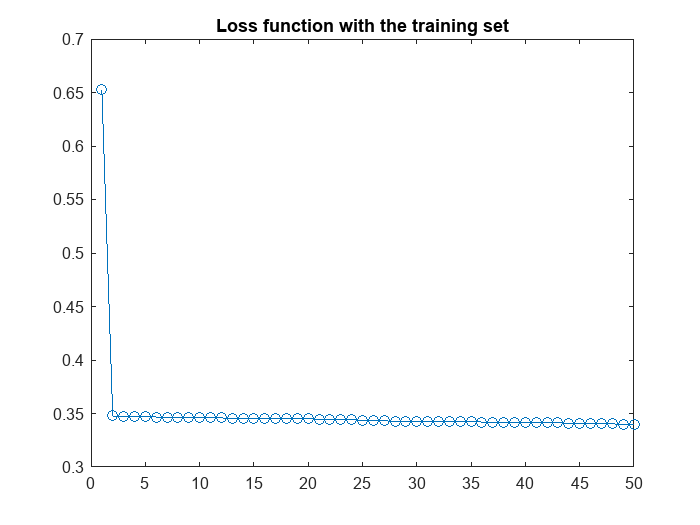

The model order suggested by the MDL criterion is equal to 2

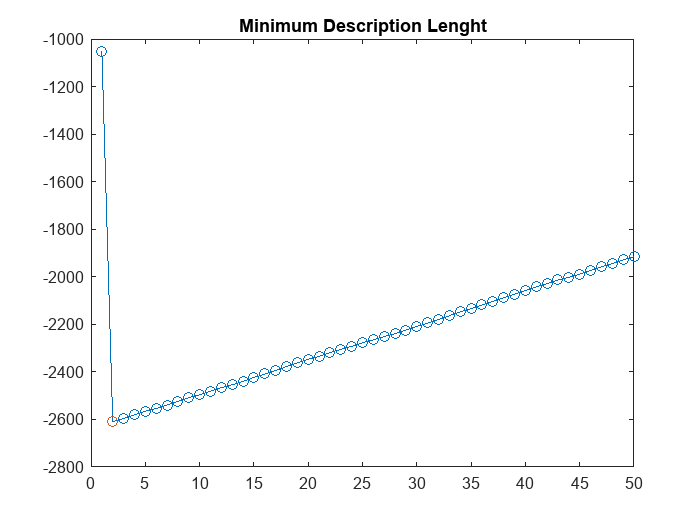

n_max=50; 
[MDL_value, MDL_min, MDL_p] =myMDL(n_max,y);

In order of verify the consistency of the result, I also** minimize the loss function over the validation set**, performing a cross-check as follows. The for-loop is almost identical to the one inside the function *myMDL *just explained, with the exception that now I have to find the minimun of the loss function, and not of the MDL values. It should be said that, even though most of the times I have obtained a consistent result, the success is not always guaranteed. In fact, the behaviour of the loss function strictly depends on the specific data set. The important thing is that the loss function  shows an increasing trend for increasing values of *p*, which it's always the case.

%Cross validation
N_half = round(N/2); % The second half of the samples is considered to be the validation set
Loss=zeros(n_max,1);
lambda = 0.999;
alpha = 2;
for p = 1:n_max
    theta_in=myLSbatch(y(1:(p*10)),p,p*10);
    theta=myRWLSIV(y((p*10):N_half),p,alpha,lambda,theta_in,p*10); % Compute the parameters' estimate over the training set                     
    %theta=myRWLSIII(y((p*10):N_half),p,lambda,theta_in,p*10);  
    [res2,W2] = myResiduals(y((N_half+1):end),theta,p,lambda);     % Compute the Loss function on the validation set
    Loss(p) = (1/N_half)*(res2')*W2*res2;    
    
end 

[minloss, p_validated] = min(Loss);
fprintf('Minimizing the loss function over the validation set, the complexity of the model results to be: %d', p_validated)

Minimizing the loss function over the validation set, the complexity of the model results to be: 2

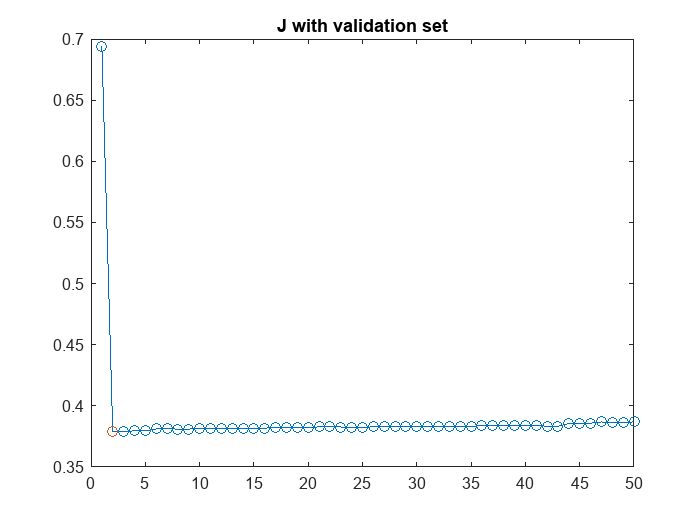

figure()
ylabel('J(theta)');
xlabel('p');
plot(Loss, '-o')
hold on
grid on
plot(p_validated, minloss, 'o')
hold off
title('J with validation set')

if (p_validated==MDL_p)
    fprintf('Check passed!')
else
    fprintf('Check failed')
end

Check passed!

Finally, the estimation of the model parameters can be obtained running the *myRWLSIV *with the model order provided by the MDL criterion: $n=p=\textrm{MDL}\_p$

theta_in_fin=myLSbatch(y(1:(MDL_p*10)),MDL_p,MDL_p*10);
%theta_estimated=myRWLSIII(y((MDL_p*10):N_half),MDL_p,lambda,theta_in_fin,MDL_p*10);
theta_estimated=myRWLSIV(y((MDL_p*10):N_half),MDL_p,alpha,lambda,theta_in_fin,MDL_p*10);
fprintf('Theta Weighted Least Square: \n') 

Theta Weighted Least Square: 


disp (theta_estimated)

    0.3623
    0.6827



### **1.4 Model validation**

In order to validate the model, in general, it's possible to perform, over the training set, the following tests on the residuals $\varepsilon \left(t\right)$:

- **whiteness test **

- crosscorrelation test between $\varepsilon \left(t\right)$ and $u\left(t\right)$

As in AR models the input is not present, just the first test can be used. Since the LS estimate is consistent, if the provided data were well described by a linear regression model, the sequence of residuals obtained should be a zero mean white process (asymptotically). Consequently, the whiteness test has the objective of verifying whether or not the residuals represent a zero mean white noise, by comparing thier autocorrelation. It's a binary statistical hyphothesis test, whose test quantity is given by:

#### 
$$x=N\frac{{\hat{r_{\varepsilon } } }^T \hat{r_{\varepsilon } } }{{\hat{r_{\varepsilon } } }^2 \left(0\right)}$$
 

where $\hat{r_{\varepsilon } }$ is the vector that cointains the first *m* sample autocorrelations of the residual. 

As it's possible to prove that:

#### 
$$\sqrt{N}\hat{r_{\varepsilon } } \underset{N\to \infty }{\longrightarrow} N\left(0,P\right)\;\;\;\;\;\textrm{with}\;\;\;\;\;P=\lim_{N\to \infty } E\left\lbrack \sqrt{N}\hat{r_{\varepsilon } } {\hat{r_{\varepsilon } } }^T \right\rbrack =\sigma_w^4 I$$


$x$ results to be Chi-Square distributed with $m$ dof.

So, the whiteness test can be transformed into a Chi-Square distribution test as:


$$\left\lbrace \begin{array}{ll}
x\le \chi_{\alpha }^2 \left(m\right) & \varepsilon \left(t,{\hat{\theta} }_N \right)\;\textrm{is}\;a\;\textrm{zero}\;\textrm{mean}\;\textrm{white}\;\textrm{process},\textrm{the}\;\textrm{model}\;\textrm{is}\;\textrm{valid}\\
x>\chi_{\alpha }^2 \left(m\right) & \textrm{the}\;\textrm{model}\;\textrm{must}\;\textrm{be}\;\textrm{rejected}
\end{array}\right.$$


The parameters to fix are:

- $\alpha$ = significance level of the set, usually set to 0.05

- $m$ = degrees of freedom of the distribution, to be chosen by taking into account also the complexity of the model, from 5 to N/4

The whiteness test is run by the function [[tfw]=myWhiteness_test(autocor,var, N, m, alpha)](matlab:open('./Functions\myWhiteness_test.m'))

%Validation
[residuals,W] = myResiduals(y(1:N_half), theta_estimated,MDL_p,lambda);    % Compute the residuals     
m=100;
alpha2=0.05;
autocorr_res=autocorr(residuals,m);     % Compute the residuals'autocorrelation
variance=var(residuals);                % Compute the variance of the residuals
autocorr_res=autocorr_res*variance;     % This operation is necessary since the autocorr function returns the 
                                        %sample autocorrelation normalized over the variance

disp(myWhiteness_test(autocorr_res(2:end),variance, N_half, m, alpha2));

The test quantity is equal to: 6.666338e+01 
The Chi-Square level's value : 1.243421e+02
The residual is a zero mean white process, so the model is valid


As last step, it's requested to compare the results obtained with different value of $\lambda$, respectively 0.99, 0.97 and 0.95. The estimations, compared to a total batch estimate, are the following:

theta_batch=myLSbatch(y,MDL_p,(length(y)-MDL_p));
lambda2 = 0.99;
theta_estimated2 = myRWLSIV(y((MDL_p*10):N_half),MDL_p,alpha,lambda2,theta_in_fin,MDL_p*10);
lambda3 = 0.97;
theta_estimated3 = myRWLSIV(y((MDL_p*10):N_half),MDL_p,alpha,lambda3,theta_in_fin,MDL_p*10);
lambda4 = 0.95;
theta_estimated4 = myRWLSIV(y((MDL_p*10):N_half),MDL_p,alpha,lambda4,theta_in_fin,MDL_p*10);

disp([theta_batch theta_estimated2 theta_estimated3 theta_estimated4])

    0.3819    0.3777    0.4701    0.5421
    0.6786    0.7001    0.6902    0.7265



Performing the whitness test for each case, it's possible to see that, as expected, the model may turn invalid as $\lambda \;$is reduced. Indeed, the memory of the algorithm might decrease too much, so that the estimate of the model parameters becomes inaccurate.

% lambda = 0.99
[residuals2,W2] = myResiduals(y(1:N_half), theta_estimated2,MDL_p,lambda2);
autocorr_res2=autocorr(residuals2,m);     
variance2=var(residuals2);                
autocorr_res2=autocorr_res2*variance2;
disp(myWhiteness_test(autocorr_res2(2:end),variance2, N_half, m, alpha2));

The test quantity is equal to: 6.775807e+01 
The Chi-Square level's value : 1.243421e+02
The residual is a zero mean white process, so the model is valid


% lambda = 0.97
[residuals3,W3] = myResiduals(y(1:N_half), theta_estimated3,MDL_p,lambda3);
autocorr_res3=autocorr(residuals3,m);     
variance3=var(residuals3);                
autocorr_res3=autocorr_res3*variance3;     
disp(myWhiteness_test(autocorr_res3(2:end),variance3, N_half, m, alpha2));

The test quantity is equal to: 1.212514e+02 
The Chi-Square level's value : 1.243421e+02
The residual is a zero mean white process, so the model is valid


% lambda = 0.95
[residuals4,W4] = myResiduals(y(1:N_half), theta_estimated4,MDL_p,lambda4);
autocorr_res4=autocorr(residuals4,m);     
variance4=var(residuals4);                
autocorr_res4=autocorr_res4*variance4;     
disp(myWhiteness_test(autocorr_res4(2:end),variance4, N_half, m, alpha2));

The test quantity is equal to: 2.042844e+02 
The Chi-Square level's value : 1.243421e+02
The test failed, the model is not valid


# Exercise 2: Classification

N=8000; % Number of samples
Student = 'Laura Calzoni';
Matriculation = '0001058438';
[FeatureSet] = ClassifyThis(N,Student,Matriculation);

% Collection of the samples
Utrain  = FeatureSet.Utrain;
Ytrain  = FeatureSet.Ytrain;
Utest   = FeatureSet.Utest;
Ytest   = FeatureSet.Ytest;


### **2.1 Understand the feature set in space**

It's possible to see immediately that the input space is $\Re^2$. In order to distinguish the inputs belonging to class 0 and 1 I divide them into two sets, displayed differently, according to the value of the corresponding outputs. In this process I also verify where is the center of the two classes, i.e. the mean, since this information will be useful later on. 

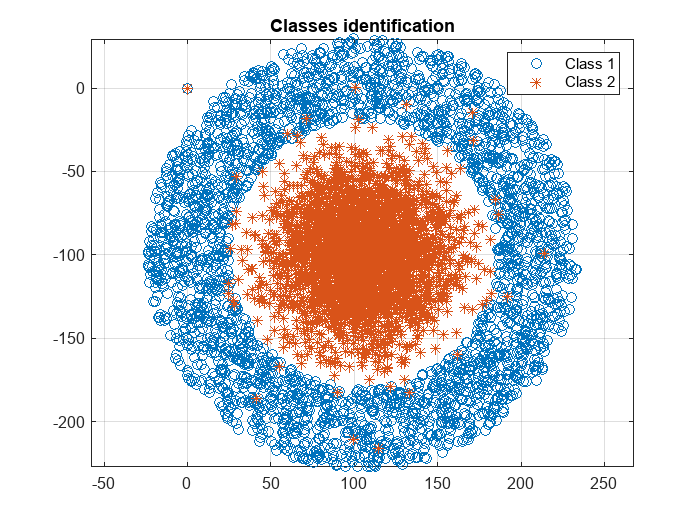

N=length(Utrain);
N1=0;       
mean1=0;
mean2=0;
for i=1:N
    if Ytrain(i)==1
        u_1(i,1)=Utrain(i,1);
        u_1(i,2)=Utrain(i,2);
        N1=N1+1;
        mean1=mean1+Utrain(i,1);    %I'am calculating the center of the classes, supposed to be the same for both 
        mean2=mean2+Utrain(i,2);
    else
        u_0(i,1)=Utrain(i,1);
        u_0(i,2)=Utrain(i,2);
    end
end

center=1/N1*[mean1,mean2];

figure()
plot(u_1(1:length(u_1),1),u_1(1:length(u_1),2),'o');
hold on 
grid on 
plot(u_0(1:length(u_1),1),u_0(1:length(u_1),2),'*');
title('Classes identification');
legend({'Class 1','Class 2'});
axis equal

I can see that my inputs are scattered in space in a **concentric spheric shape**, **with center not in the origin**. In order to be able to apply **Logistic Regression **I have to use a non linear transformation on the input space thanks to which the decision boundary, in the new input space, becomes linear. In this case, the transformation to use is the following:

#### 
$$U\left(t\right)=\left\lbrack u_{1\;} \left(t\right)\;\;u_2 \left(t\right)\right\rbrack \;\longrightarrow \;\bar{U} \left(t\right)=\left\lbrack \;{\left(u_1 \left(t\right)-\textrm{center}\right)}^2 \;\;\;{\left(u_2 \left(t\right)-\textrm{center}\right)}^2 \right\rbrack$$


which, unusually, doesn't imply an enlargement of the final input space dimension (the complexity of the model remains the same). However, in $\;\bar{U} \left(t\right)$ class overlap may result increased. 

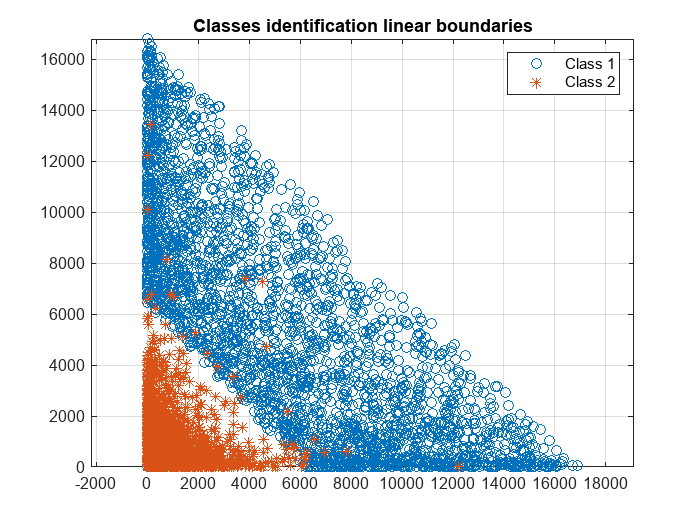

for i=1:N
     Unl(i,1)=((Utrain(i,1)-center(1))*(Utrain(i,1)-center(1)));  
     Unl(i,2)=((Utrain(i,2)-center(2))*(Utrain(i,2)-center(2)));
end

for i=1:N
    if Ytrain(i)==1
        u_1(i,1)=Unl(i,1);
        u_1(i,2)=Unl(i,2);
    else
        u_0(i,1)=Unl(i,1);
        u_0(i,2)=Unl(i,2);
    end
end

figure();
plot(u_1(1:length(u_1),1),u_1(1:length(u_1),2),'o');
hold on 
grid on 
plot(u_0(1:length(u_1),1),u_0(1:length(u_1),2),'*');
title('Classes identification linear boundaries');
legend({'Class 1','Class 2'});
axis equal
hold off

### **2.2 Definition of the required classification algorithm **

Logistic regression is based on finding the parameter vector that describes the decision boundary. In $\;\bar{U} \left(t\right)$ the boundary is linear and it can be rewritten in linear regression form as:


$${z\left(t\right)=\varphi }^T \left(t\right)\theta =0\;\;\;\;\;\;\textrm{with}\;\;\;\;$$

$$\begin{array}{l}
\varphi^T \left(t\right)={\left\lbrack 1\;\;\;{\left(u_1 \left(t\right)-\mathrm{center}\right)}^2 \;\;\;{\left(u_2 \left(t\right)-\mathrm{center}\right)}^2 \;\;\right\rbrack }^T \\
\theta =\left\lbrack {\;\beta }_0 \;\;\beta_1 \;\;\beta_2 \;\right\rbrack \;\;\mathrm{parameter}\;\mathrm{vector}\;\mathrm{to}\;\mathrm{estimate}
\end{array}$$


It can be demonstrated that the estimate of $\theta$ is solution of the optimization problem :

#### 
$$\min_{\theta } \;J\left(\theta \right)\;\;\;\;\;\;\;\;\;\;\mathrm{with}\;$$

$$\;J\left(\theta \right)=-\mathrm{logP}\left(Y\left|\theta \right.\right)=-\sum_{t=1}^N \left\lbrack y\left(t\right)\log \left(f\left(z\left(t\right)\right)\right)+\left(1-y\left(t\right)\right)\log \left(1-f\left(z\left(t\right)\right)\right)\right\rbrack$$


where $Y$ is the output vector, $N$ is the number of samples of the training set and $f\left(z\left(t\right)\right)$ is the Logistic Sigmoid defined as $f\left(z\left(t\right)\right)=\frac{e^{z\left(t\right)} }{1+e^{z\left(t\right)} }$ (implemented in the function [F = myLogisticSigmoid(z)](matlab:open('./Functions\myLogisticSigmoid.m'))). This operation can be performed using the **Newton Rapson iterative algorithm, **according to which the k-th iteration results:

#### 
$$\;\hat{\theta^{k+1} } =\hat{\theta^k } -\eta^k J^" {\left(\hat{\theta^k } \right)}^{-1} J^{\prime {\left(\hat{\theta^k } \right)}^T }$$
 

where 

- $\eta^k$ is the step size, used to improve convergency

- $J^{\prime } \left(\theta \right)$ is the gradient of the loss function, computed by the function [J_grad = myGradient(Phi,Theta,Y)](matlab:open('./Functions\myGradient.m')) and defined as:


$$J^{\prime } \left(\theta \right)=\phi^T \left(F\left(\theta \right)-Y\right)\;\;\;\;\;\;\;\;\textrm{with}\;\;\;\;\phi =\left\lbrack \begin{array}{ccc}
1 & u_1 \left(1\right) & u_2 \left(1\right)\\
\vdots  & \vdots  & \vdots \\
1 & u_1 \left(N\right) & u_2 \left(N\right)
\end{array}\right\rbrack \;\;\;\;\;\;Y=\left\lbrack \begin{array}{c}
y\left(1\right)\\
\vdots \\
y\left(N\right)
\end{array}\right\rbrack \;\;\;\;\;F\left(\theta \right)=\left\lbrack \begin{array}{c}
f\left(z\left(1\right)\right)\\
\vdots \\
f\left(z\left(N\right)\right)
\end{array}\right\rbrack$$


- $J^" \left(\theta \right)$ is the hessian of the loss function, implemented in [J_hess= myHessian(Phi,Theta)](matlab:open('./Functions\myHessian.m')) and defined as:                  


$$J^" \left(\theta \right)=\phi^T W\left(\theta \right)\phi \;\;\;\;\;\;\;\;\textrm{with}\;\;\;W\left(\theta \right)=\left\lbrack \begin{array}{ccc}
f\left(z\left(1\right)\right)\left(1-f\left(z\left(1\right)\right)\right) &  & 0\\
 & \ddots  & \\
0 &  & f\left(z\left(N\right)\right)\left(1-f\left(z\left(n\right)\right)\right)
\end{array}\right\rbrack$$
 

Among all the possible stopping criterions, I decide to adopth the following:

#### 
$$\frac{\left|\right|\hat{\theta^{k+1} } -\hat{\theta^k } \left|\right|}{\left|\right|\hat{\theta^k } \left|\right|}<\delta$$


with the threshold $\delta \;$set to 0.01.

Once $\hat{\theta}$ has been computed, when a new input becomes available it is classified according to the discriminant function $f\left(\hat{z} \left(t\right)\right),\;$with $\hat{z} \left(t\right)=\varphi^T \left(t\right)\hat{\theta}$, as follows: if $f\left(\hat{z} \left(t\right)\right)>0\ldotp 5$ the input is assigned to class $C_1$, otherwise it belongs to class $C_2 \ldotp$

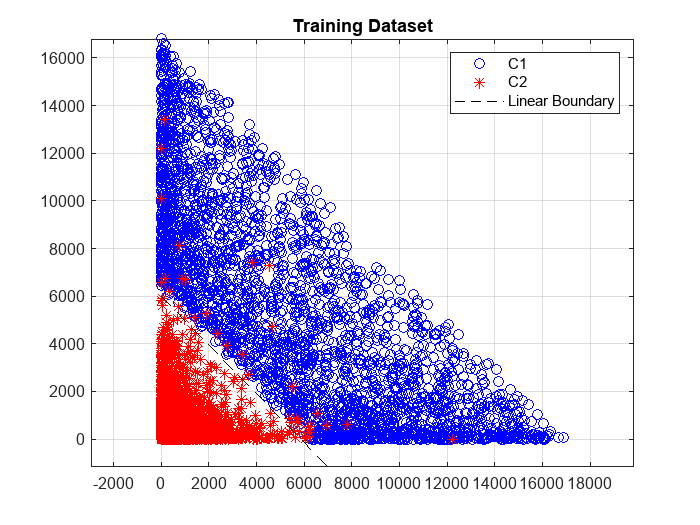

phi_training=[ones(N,1) Unl];
eta=1;              % Step size
delta=0.01;         % Threshold
theta_0=zeros(3,1); % Inizialization of theta

theta_k=theta_0;
stop_value=1000;    % set initially to an extremely (impossible) high value

figure();
while(stop_value>=delta)
    J_grad=myGradient(phi_training,theta_k,Ytrain);
    J_hess=myHessian(phi_training,theta_k);
    theta_k_plus_1=theta_k-eta*J_hess^(-1)*J_grad;
    stop_value=norm(theta_k_plus_1-theta_k)/norm(theta_k);
    theta_k=theta_k_plus_1;
    

    plot(Unl(find(Ytrain>0.5),1),Unl(find(Ytrain>0.5),2),'bo'); %C1
    hold on
    grid on
    plot(Unl(find(Ytrain<0.5),1),Unl(find(Ytrain<0.5),2),'r*'); %C2
    xspace = linspace(0,7000);
    BoundaryLine = (theta_k(1) + xspace.*theta_k(2))./(-theta_k(3));
    plot(xspace,BoundaryLine,'--k');
    axis equal
    hold off
    title('Training Dataset');
    legend({'C1','C2','Linear Boundary'});
end

I can plot my estimated parameter vector with:

disp (theta_k)

  -12.1127
    0.0021
    0.0020



### **2.3 Verification of the obtained classificator**

To evaluate the performance of the classificator I can compute **error rate on the training set** (training error rate), which represents the fraction of the missclassified observations:

#### 
$$E_r =\frac{1}{N}\sum_{t=1}^N I\left(y\left(t\right),\hat{y} \left(t\right)\right)$$


$\hat{y} \left(t\right)$ is the prediction of $y\left(t\right)$ provided by the estimated classifier, while $I\left(y\left(t\right),\hat{y} \left(t\right)\right)$ is called indicator variable and it gives 1 when $y\left(t\right)\not= \hat{y} \left(t\right)$ and 0 otherwise.The error rate is implemented in the function [Er = myErrorRate(y_hat,y)](matlab:open('./Functions\myErrorRate.m')).

f=myLogisticSigmoid(phi_training*theta_k);
y_hat=double(f>0.5);

training_error_rate=myErrorRate(y_hat,Ytrain)*100

training_error_rate = 0.6786

Then, in order to test my classificator, I proceed by trying it on the **test data set.** Again, the input space must be transformed also for thet test set, as I did for the training one:

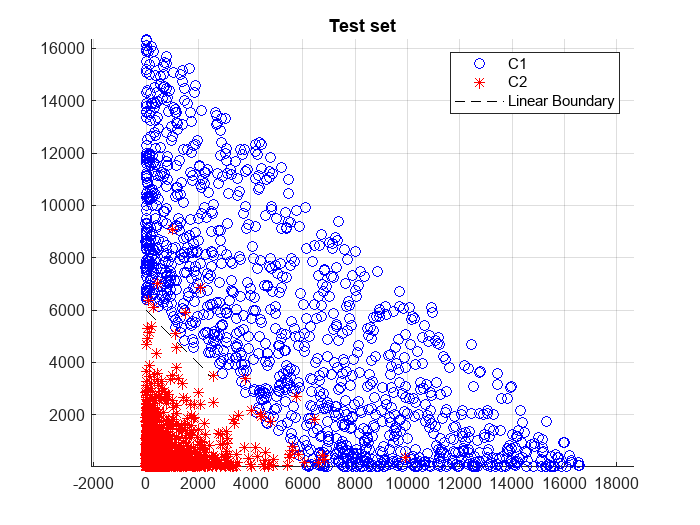

%test set
Ntest=length(Utest);
for i=1:Ntest
     Unl_test(i,1)=((Utest(i,1)-center(1))*(Utest(i,1)-center(1)));  
     Unl_test(i,2)=((Utest(i,2)-center(2))*(Utest(i,2)-center(2))); 
end

phi_test=[ones(Ntest,1) Unl_test];

figure();
hold on
grid on
plot(Unl_test(find(Ytest>0.5),1),Unl_test(find(Ytest>0.5),2),'bo');  %C1
plot(Unl_test(find(Ytest<0.5),1),Unl_test(find(Ytest<0.5),2),'r*');  %C2
title('Test set');
xspace = linspace(0,2500);
BoundaryLine = (theta_k(1) + xspace.*theta_k(2))./(-theta_k(3));
plot(xspace,BoundaryLine,'--k');
legend({'C1','C2','Linear Boundary'});
axis equal
hold off

Then, it's possible to compute the error rate also on the test set (test error rate). It should be noticed that, however, the same parameter vector *theta_k, *estimated in the previous step, must be used (otherwise I don't perform the test correctly). For this reason, the test error rate is expected to be a little higher.  

f_test=myLogisticSigmoid(phi_test*theta_k);
y_hat_test=double(f_test>0.5);
test_error_rate=myErrorRate(y_hat_test,Ytest)*100

test_error_rate = 1

### **2.4 Comparison agaist matlab**

MATLAB already provides the buit-in function *mnrfit()* thanks to which the classifier can be obtained straightforwardly, given the training data set.  I can exploit this function and use the resulting classificator on the test set. If my classifier was good, the new test error rate would be similar to the former one.

%Battle against Matlab
theta_true = -mnrfit(Unl,Ytrain+1);
disp([theta_k theta_true])

  -12.1127  -12.1130
    0.0021    0.0021
    0.0020    0.0020



f_true=myLogisticSigmoid(phi_test*theta_true);
y_hat_true=double(f_true>0.5);
test_error_rate_true=myErrorRate(y_hat_true,Ytest)*100

test_error_rate_true = 1